1.x =[2,2,2],  h=[2,2,2] 做卷積，另依下側條件各做一次卷積。

- **試改變x，再觀察y。**

- **試改變h，再觀察y。**

**問題**

- 問輸出為何? (3組答案)                         **(8分)**

- 請將輸出畫圖。 (3張圖)  **(4分)**

- 將數學推導詳細列出。(由題目那組推導)         **(4分)**

- 輸出的長度與x, h 之間的長度有何關係?       **(9分)**

x=[2,2,2]

x =      2     2     2


h=[2,2,2,3]

h =      2     2     2     3


c=conv(x,h)

c =      4     8    12    14    10     6


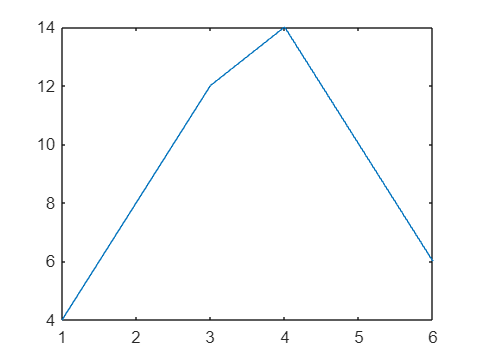


plot(c)


x=[2,2,2]

x =      2     2     2


h=[2,2,2,3]

h =      2     2     2     3


c=conv(x,h)

c =      4     8    12    14    10     6


plot(c)


x=[2,2,4]

x =      2     2     4


h=[2,2,2]

h =      2     2     2


c=conv(x,h)

c =      4     8    16    12     8


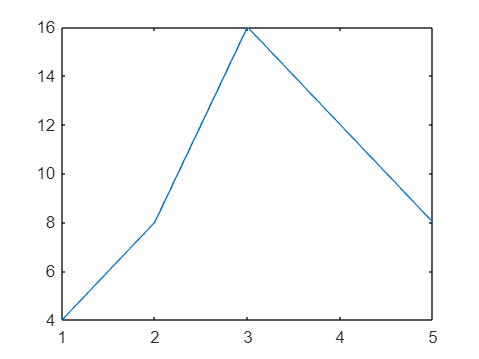

plot(c)


%X與h是因為 h反轉再重合相乘
%兩個vector的長度相加減一

2.請問下列卷積後輸出為何?

- x= cos(2*pi*f*time) [Lab 3 FFT 範例], h=[1,1,1]       **(15分)**

- x=[2 1; 3 2 ], h=[-1 1; 2 1]                                         **(10分)**

N=256

N = 256

fs=8000

fs = 8000

freqStep=fs/N

freqStep = 31.2500

time=(0:N-1)/fs

time =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


f=10*freqStep

f = 312.5000

x= cos(2*pi*f*time)

x =     1.0000    0.9700    0.8819    0.7410    0.5556    0.3369    0.0980   -0.1467   -0.3827   -0.5957   -0.7730   -0.9040   -0.9808   -0.9988   -0.9569   -0.8577   -0.7071   -0.5141   -0.2903   -0.0491    0.1951    0.4276    0.6344    0.8032    0.9239    0.9892    0.9952    0.9415    0.8315    0.6716    0.4714    0.2430    0.0000   -0.2430   -0.4714   -0.6716   -0.8315   -0.9415   -0.9952   -0.9892   -0.9239   -0.8032   -0.6344   -0.4276   -0.1951    0.0491    0.2903    0.5141    0.7071    0.8577


h=[1,1,1]

h =      1     1     1


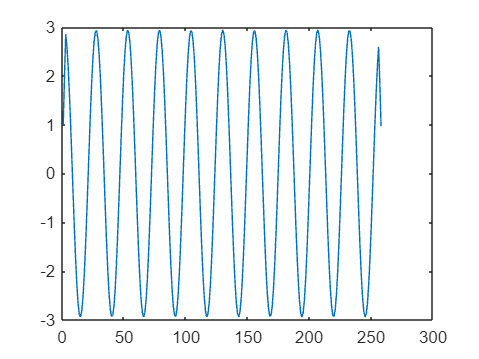

imp = [1; zeros(49,1)];
plot(conv(x,h))

x=[2 1; 3 2 ]

x =      2     1
     3     2


h=[-1 1; 2 1]

h =     -1     1
     2     1


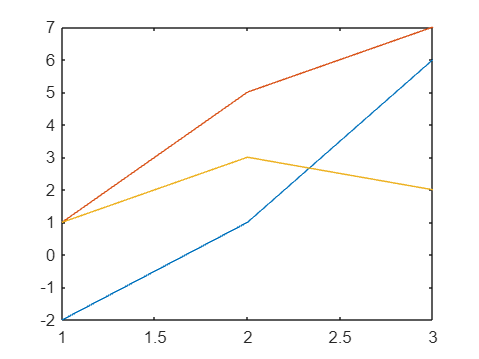

plot(conv2(x,h))
axis tight

3.兩個系統皆具有脈衝響應(impulse responses)，並使用MATLAB指令繪製階躍響應(step responses)後的結果。**(25%)**

t=-5:1:5

t =     -5    -4    -3    -2    -1     0     1     2     3     4     5


h1=[0.25 0.25 0.25 0.25 zeros(1,6)]

h1 =     0.2500    0.2500    0.2500    0.2500         0         0         0         0         0         0


h2=[0.25 -0.25 -0.25 0.25 zeros(1,6)]

h2 =     0.2500   -0.2500   -0.2500    0.2500         0         0         0         0         0         0


y =          0         0         0         0         0    0.5000    1.0000    1.0000    1.0000    1.0000    1.0000


x=conv(h1,heaviside(t))

x =          0         0         0         0         0    0.1250    0.3750    0.6250    0.8750    1.0000    1.0000    0.7500    0.5000    0.2500         0         0         0         0         0         0


x1=conv(h2,heaviside(t))

x1 =          0         0         0         0         0    0.1250    0.1250   -0.1250   -0.1250         0         0   -0.2500         0    0.2500         0         0         0         0         0         0


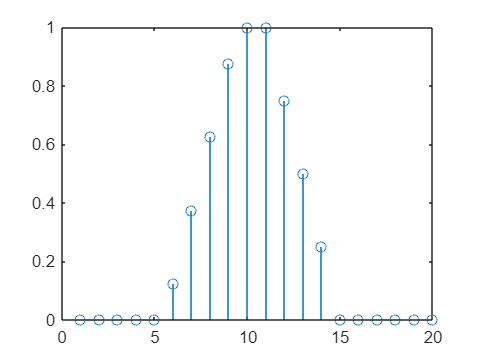


stem(x)

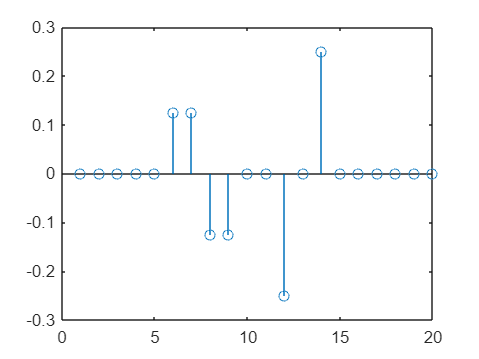

stem(x1)

4.使用MATLAB指令，繪製以下捲積圖，

y(t) = (e-at‧u (t))＊(cos2πft‧u(t))，其中從 t=0 到 3、a=2、f=20 

**繪製 y(t) 整段訊號。 **                                **(25分)**

- **給定 t and u(t)，Δt = 0.1。**

- **使用函式: x1 = ****e****-at****‧u (t)**

- **使用函式: x2 = ****cos2πft‧u(t)**

- **使用函式: y = x1 * x2**

t= 0:0.1:3

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000


a=2

a = 2

f=20

f = 20


%x1=(exp())
x1 = exp(-a*t).*heaviside(t)

x1 =     0.5000    0.8187    0.6703    0.5488    0.4493    0.3679    0.3012    0.2466    0.2019    0.1653    0.1353    0.1108    0.0907    0.0743    0.0608    0.0498    0.0408    0.0334    0.0273    0.0224    0.0183    0.0150    0.0123    0.0101    0.0082    0.0067    0.0055    0.0045    0.0037    0.0030    0.0025


x2 = cos(2*pi*f*t).*heaviside(t)

x2 =     0.5000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


y=conv(x1,x2)

y =     0.2500    0.9094    1.6539    2.2635    2.7625    3.1711    3.5057    3.7796    4.0038    4.1874    4.3377    4.4608    4.5616    4.6441    4.7116    4.7669    4.8122    4.8492    4.8796    4.9044    4.9248    4.9414    4.9551    4.9662    4.9754    4.9829    4.9890    4.9940    4.9981    5.0015    5.0042    4.5055    3.6867    3.0164    2.4676    2.0183    1.6504    1.3492    1.1026    0.9007    0.7354    0.6001    0.4893    0.3985    0.3243    0.2635    0.2137    0.1729    0.1395    0.1122


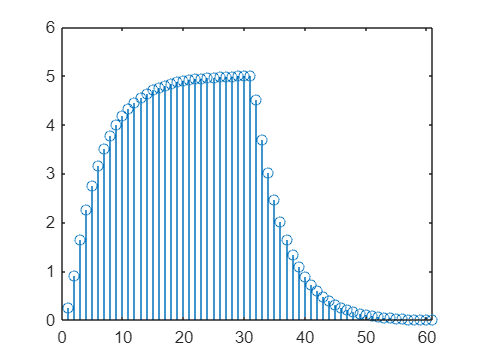


stem(y)